# graph_SP.mlx

`../output/kob_test_36sec_2.csv`の図示

SP

`graph.m`は内容同じ

clear;
close all;

df = readtable('../output/kob_test_36sec_SP.csv');
head(df)

ans = 8×9 table
         time            day        short_radi    salinity_wc    salinity_pw     tide        psi_wc         psi_pw       Jv_upward 
    ______________    __________    __________    ___________    ___________    _______    ___________    ___________    __________

    {'0D09:59:59'}             0      831.85         34.99         33.498       0.59918    -2.4818e+06    -2.3726e+06    7.2831e-05
    {'0D10:00:35'}    0.00041667      833.35        34.987         33.497       0.59893    -2.4816e+06    -2.3725e+06     7.271e-05
    {'0D10:01:11'}    0.00083333      834.85        34.984         33.497       0.59868    -2.4814e+06    -2.3725e+06     7.259e-05
    {'0D10:01:47'}       0.00125      836.35         34.98         33.496       0.59844    -2.4811e+06    -2.3724e+06    7.2469e-05
    {'0D10:02:23'}     0.0016667      837.83        34.977         33.495       0.59819    -2.4809e+06    -2.3724e+06    7.2348e-05
    {'0D10:02:59'}     0.0020833      839.31        34.974 

height(df)

ans = 2401

row_count = transpose(1:1:height(df));
newNames = "row_count";
df = addvars(df,row_count,'NewvariableNames',newNames)

df = 2401×10 table
         time            day        short_radi    salinity_wc    salinity_pw     tide        psi_wc         psi_pw       Jv_upward     row_count
    ______________    __________    __________    ___________    ___________    _______    ___________    ___________    __________    _________

    {'0D09:59:59'}             0      831.85         34.99         33.498       0.59918    -2.4818e+06    -2.3726e+06    7.2831e-05        1    
    {'0D10:00:35'}    0.00041667      833.35        34.987         33.497       0.59893    -2.4816e+06    -2.3725e+06     7.271e-05        2    
    {'0D10:01:11'}    0.00083333      834.85        34.984         33.497       0.59868    -2.4814e+06    -2.3725e+06     7.259e-05        3    
    {'0D10:01:47'}       0.00125      836.35         34.98         33.496       0.59844    -2.4811e+06    -2.3724e+06    7.2469e-05        4    
    {'0D10:02:23'}     0.0016667      837.83        34.977         33.495       0.59819    -2.4809e+06    -2.3

% df.hour = df.t_min / 60;
df.psi_wc = df.psi_wc / 1000000;
df.psi_pw = df.psi_pw / 1000000;

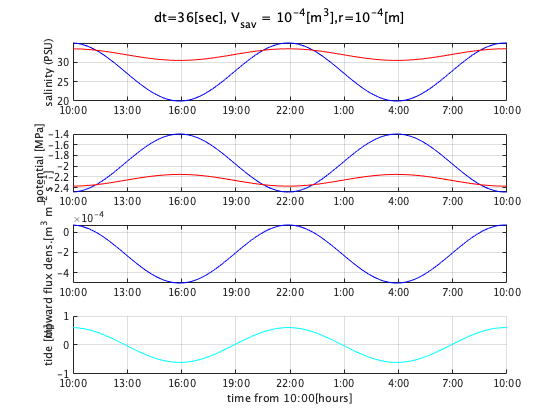

xl = [1 height(df)];
xticks_num = [1 301 601 901 1201 1501 1801 2101 2401];
xticks_hourname = {'10:00','13:00','16:00','19:00','22:00','1:00','4:00','7:00','10:00'};

subplot(4,1,1)
sgtitle('dt=36[sec], V_{sav} = 10^{-4}[m^3],r=10^{-4}[m]');
x  = df.row_count;
y1 = df.salinity_wc;
y2 = df.salinity_pw;
plot(x,y1,'b',x,y2,'r')
% clear ylim
xlim(xl);
% ylim([33 38]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([33 34 35 36 37 38]);
ylabel('salinity (PSU)');
grid on;

subplot(4,1,2)
y4 = df.psi_wc;
y5 = df.psi_pw;

plot(x,y4,'b',x,y5,'r')
xlim(xl);
% ylim([-2.7 -2.3]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([-2.7 -2.6 -2.5 -2.4 -2.3]);
ylabel('potential [MPa]');
grid on;

subplot(4,1,3)
y8 = df.Jv_upward;
plot(x,y8,'b')
xlim(xl);
% ylim([0.2 0.6]);
xticks(xticks_num);
xticklabels(xticks_hourname);
% yticks([0.2 0.3 0.4 0.5 0.6]);
% clear xticklabels
% xticklabels({});
ylabel('Upward flux dens.[ms^{-1}]');
grid on;

subplot(4,1,4)
y10 = df.tide;
hold on
plot(x,y10,'Color','c','Marker','none')
clear ylim
ylim([-1 1])
% yticks([-1 0 1]);
ylabel('tide [m]');

xlim(xl);
xticks(xticks_num);
xticklabels(xticks_hourname);
xlabel('time from 10:00[hours]');
grid on
hold off